# HW3 Gabe Colangelo

clear
close all
warning off
clc

syms x1 x2 x3 x4 x5 x6 u1 u2 u3 x(t) x_dot(t) theta1(t) theta_dot_1(t)...
     theta2(t) theta_dot_2(t) t theta_ddot_1 x_ddot theta_ddot_2...
     m1 m2 M L1 L2 g real

% Numeric System Parameters
m1_num  = 0.5;
L1_num  = 0.5;
m2_num  = 0.75;
L2_num  = 0.75;
M_num   = 1.5;
g_num   = 9.81;


## Problem 1 - Equilibrium Input for single input

% Equilibrium States
xe      = [0.1, deg2rad(60), deg2rad(45),  0, 0, 0 ]';

% Non-linear Model with single input
xdot    = DIPC_1([],xe,u1,m1_num,m2_num,M_num,L1_num,L2_num,g_num);

% Solve for ue if it exists
ue_1    = solve(xdot == 0,u1);

if isempty(ue_1)
    disp('There does not exist a u_e such that a single input can acheive the desired equilibirum state')
end

There does not exist a u_e such that a single input can acheive the desired equilibirum state


## Problem 2 - Equilibrium Input for two inputs

% Non-linear Model with two inputs
xdot_2   = DIPC_2([],xe,[u1;u2],m1_num,m2_num,M_num,L1_num,L2_num,g_num);

% Solve for ue if it exists
sol_2    = solve(xdot_2 == 0,[u1;u2]);
ue_2     = [sol_2.u1;sol_2.u2];

if isempty(ue_2)
    disp('There does not exist a u_e such that two inputs can achieve the desired equilibrium state')
end

There does not exist a u_e such that two inputs can achieve the desired equilibrium state


## Problem 3 - Equilibrium Input for Three inputs

% Call Lagrangian for DIPC 
L           = DIPC_Lagrangian(t,x,x_dot, theta1, theta_dot_1, theta2, theta_dot_2, M, m1,m2, L1, L2, g);

% Solve Lagrange's Equations of Motion
% q = x, Q = u1
eqn_x       = subs(simplify(diff(diff(L,x_dot),t) - diff(L,x)),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t), diff(x_dot,t), diff(theta_dot_1(t), t), diff(theta_dot_2(t), t)],...
             [x_dot, theta_dot_1, theta_dot_2, x_ddot, theta_ddot_1, theta_ddot_2]) == u1;

% q = theta1, Q = u2
eqn_theta1  = subs(simplify(diff(diff(L,theta_dot_1),t) - diff(L,theta1)),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t), diff(x_dot,t), diff(theta_dot_1(t), t), diff(theta_dot_2(t), t)],...
             [x_dot, theta_dot_1, theta_dot_2, x_ddot, theta_ddot_1, theta_ddot_2]) == u2;

% q = theta2, Q = u3
eqn_theta2  = subs(simplify(diff(diff(L,theta_dot_2),t) - diff(L,theta2)),[diff(x(t),t), diff(theta1(t),t)...
             ,diff(theta2(t),t), diff(x_dot,t), diff(theta_dot_1(t), t), diff(theta_dot_2(t), t)],...
             [x_dot, theta_dot_1, theta_dot_2, x_ddot, theta_ddot_1, theta_ddot_2]) == u3;

% Solve system of equations for 2nd derivative of states
sys_eqn     = solve([eqn_x,eqn_theta1,eqn_theta2],[x_ddot,theta_ddot_1,theta_ddot_2]);

% Put EOM into state space form
x4_dot      = subs(simplify(sys_eqn.x_ddot),[x theta1 theta2 x_dot theta_dot_1 theta_dot_2],[x1 x2 x3 x4 x5 x6]);
x5_dot      = subs(simplify(sys_eqn.theta_ddot_1),[x theta1 theta2 x_dot theta_dot_1 theta_dot_2],[x1 x2 x3 x4 x5 x6]);
x6_dot      = subs(simplify(sys_eqn.theta_ddot_2),[x theta1 theta2 x_dot theta_dot_1 theta_dot_2],[x1 x2 x3 x4 x5 x6]);

% Use fsolve to find ue if it exists
fsol_opt    = optimset('Display','off');
fun         = @(u)DIPC_3([],xe,u,m1_num,m2_num,M_num,L1_num,L2_num,g_num);

disp('There does not exist a u_e such that two inputs can achieve the desired equilibrium state')

There does not exist a u_e such that two inputs can achieve the desired equilibrium state


ue          = fsolve(fun,[0 0 0]',fsol_opt)

ue =     0.0000
   -5.3098
   -3.9019


## Problem 4 - Taylor Series Expansion

% Non-linear System
f       = DIPC_3([],[x1;x2;x3;x4;x5;x6],[u1;u2;u3],m1_num,m2_num,M_num,L1_num,L2_num,g_num);
h       = [x1;x2;x3];

% Equilibrium output
ye      = double(subs(h,[x1;x2;x3;x4;x5;x6],xe));

disp('The linearized state space model matrices are given by')

The linearized state space model matrices are given by


% Jacobian Matrices/ Linearized Model about equilibrium pair
A       = double(subs(jacobian(f,[x1;x2;x3;x4;x5;x6]),[x1;x2;x3;x4;x5;x6;u1;u2;u3],[xe;ue]))

A =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -0.5341   -1.1264         0         0         0
         0   22.5046  -17.8041         0         0         0
         0  -13.9883   21.7759         0         0         0


B       = double(subs(jacobian(f,[u1;u2;u3]),[x1;x2;x3;x4;x5;x6;u1;u2;u3],[xe;ue]))

B =          0         0         0
         0         0         0
         0         0         0
    0.4252   -0.1742   -0.2887
   -0.1742    7.3409   -4.5629
   -0.2887   -4.5629    5.5808


C       = double(jacobian(h,[x1;x2;x3;x4;x5;x6]))

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0


D       = double(jacobian(h,[u1;u2;u3]))

D =      0     0     0
     0     0     0
     0     0     0


del_x   = [x1;x2;x3;x4;x5;x6] - xe;
del_u   = [u1;u2;u3] - ue;

disp('The Taylor series expansion about (xe,ue) is: ')

The Taylor series expansion about (xe,ue) is: 



$$\delta \dot{x} = A (x - x_e) + B (u - u_e)
\\
\delta y = C(x - x_e) + D (u - u_e)$$


del_xdot= vpa(A*del_x + B*del_u,4)

$$del\_xdot = \left(\begin{array}{c} x_{4}\\ x_{5}\\ x_{6}\\ 0.4252\,u_{1}-0.1742\,u_{2}-0.2887\,u_{3}-0.5341\,x_{2}-1.126\,x_{3}-0.6075\\ 7.341\,u_{2}-0.1742\,u_{1}-4.563\,u_{3}+22.5\,x_{2}-17.8\,x_{3}+11.59\\ 5.581\,u_{3}-4.563\,u_{2}-0.2887\,u_{1}-13.99\,x_{2}+21.78\,x_{3}-4.907 \end{array}\right)$$

del_y   = vpa(C*del_x + D*del_u,4)

$$del\_y = \left(\begin{array}{c} x_{1}-0.1\\ x_{2}-1.047\\ x_{3}-0.7854 \end{array}\right)$$

## Problem 5 - State Feedback Controller Design

% Check system controllability
co     = ctrb(A,B);

if rank(co) == length(A)
    disp('The pair (A,B) is controllable')
end

The pair (A,B) is controllable


% Get dimensions of B
[n, m] = size(B);

% Controller Robustness Term
alpha_K= 2;

% Use CVX to solve matrix inequality and determine K
cvx_begin sdp quiet

% Variable definition
variable S(n, n) symmetric
variable Z(m, n)

% LMIs
S*A' + A*S -Z'*B'- B*Z +2*alpha_K*S <= -eps*eye(n);
S >= eps*eye(n);
cvx_end

disp('The linear state-feedback controller applied to the non-linear model is: u = -K*del_x + u_e')

The linear state-feedback controller applied to the non-linear model is: u = -K*del_x + u_e



$$u = u_e + \delta u = u_e  -K\delta x = u_e - K(x - x_e) = u_e - Kx +K x_e$$


disp('The control gains for the applied control law are:')

The control gains for the applied control law are:


% compute K matrix
K = Z/S

K =    46.5967    5.9210    7.6456   20.5268    2.6616    3.3223
    4.0451    8.0484    3.3714    2.2284    2.2719    2.0270
    5.2509    2.7333   11.4612    2.9236    2.0400    3.1918


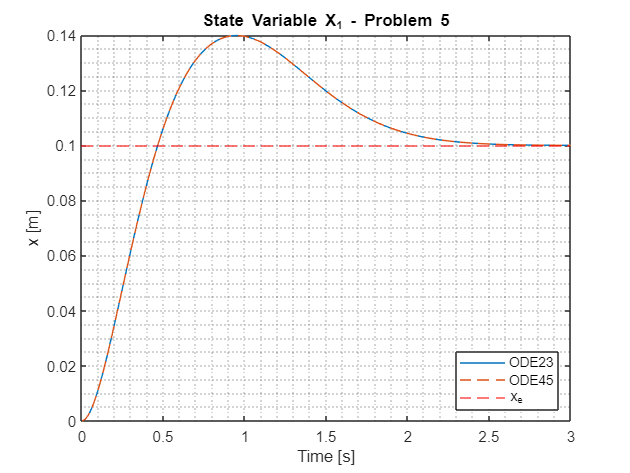

% State IC  [m, rad, rad, m/s, rad/s, rad/s]
x0          = [0 .01 .02 0 0 0]';  

% Time interval and vector
dt          = 1/200;
time        = (0:dt:3)';

% ODE solver options
options     = odeset('AbsTol',1e-8,'RelTol',1e-8);

% ODE45 Function call
[~, X_ode45] = ode45(@(t,x) ControlledDIPC_3([], x, xe, ue, K, m1_num, m2_num, M_num, L1_num, L2_num, g_num), time, x0, options);

% ODE23 Function call
[~, X_ode23] = ode23(@(t,x) ControlledDIPC_3([], x, xe, ue, K, m1_num, m2_num, M_num, L1_num, L2_num, g_num), time, x0, options);

figure
plot(time,X_ode23(:,1),time, X_ode45(:,1),'--')
yline(xe(1),'--r')
title('State Variable X_1 - Problem 5')
legend('ODE23','ODE45','x_1_e','Location','southeast')
ylabel('x [m]')
grid minor
xlabel('Time [s]')

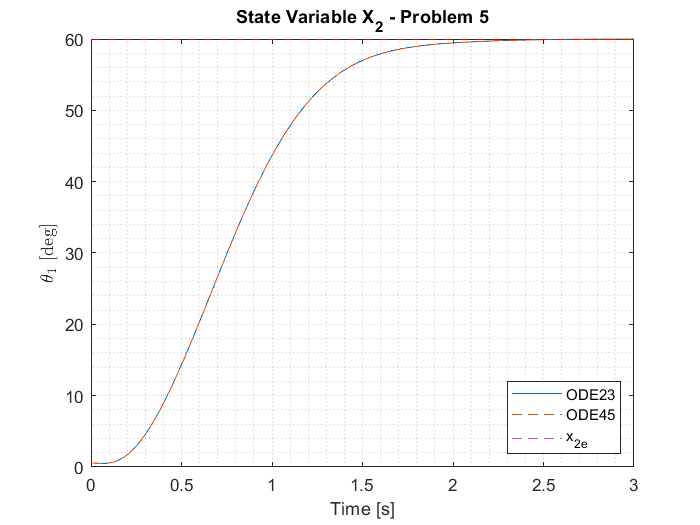

figure
plot(time,X_ode23(:,2)*180/pi,time, X_ode45(:,2)*180/pi,'--')
yline(xe(2)*180/pi,'--r')
title('State Variable X_2 - Problem 5')
ylabel('$\theta_1$ [deg]','Interpreter','latex')
grid minor
xlabel('Time [s]')
legend('ODE23','ODE45','x_2_e','Location','southeast')

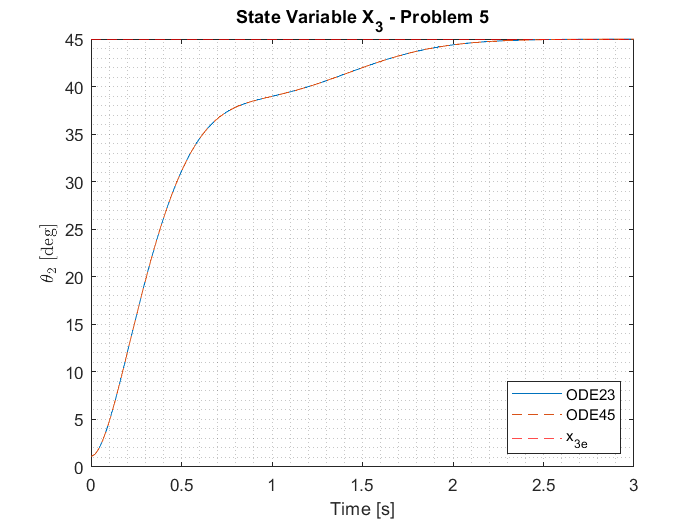

figure
plot(time,X_ode23(:,3)*180/pi,time, X_ode45(:,3)*180/pi,'--')
yline(xe(3)*180/pi,'--r')
title('State Variable X_3 - Problem 5')
ylabel('$\theta_2$ [deg]','Interpreter','latex')
grid minor
xlabel('Time [s]')
legend('ODE23','ODE45','x_3_e','Location','southeast')

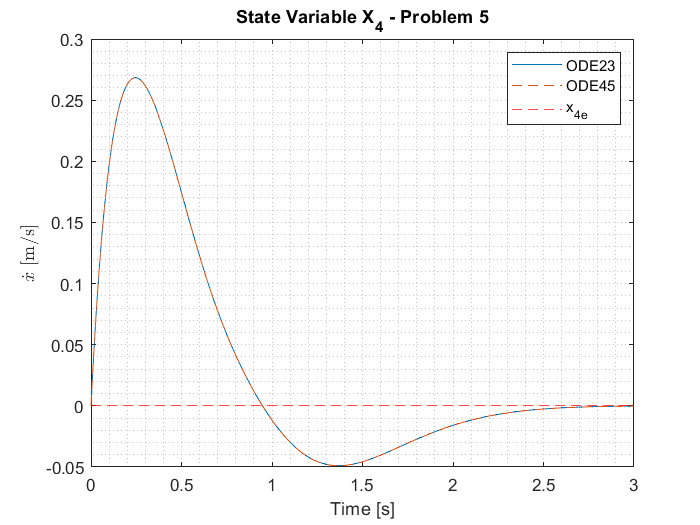

figure
plot(time,X_ode23(:,4),time, X_ode45(:,4),'--')
yline(xe(4),'--r')
title('State Variable X_4 - Problem 5')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid minor
xlabel('Time [s]')
legend('ODE23','ODE45','x_4_e')

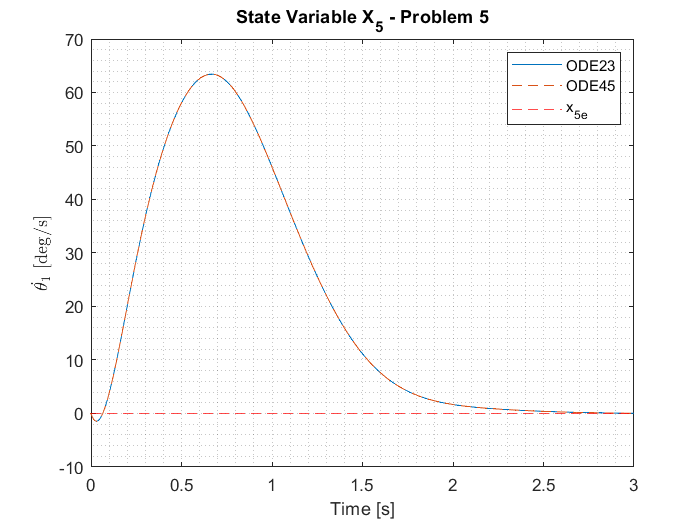

figure
plot(time,X_ode23(:,5)*180/pi,time, X_ode45(:,5)*180/pi,'--')
yline(xe(5)*180/pi,'--r')
title('State Variable X_5 - Problem 5')
ylabel('$\dot{\theta_1}$ [deg/s]','Interpreter','latex')
xlabel('Time [s]')
grid minor
legend('ODE23','ODE45','x_5_e')

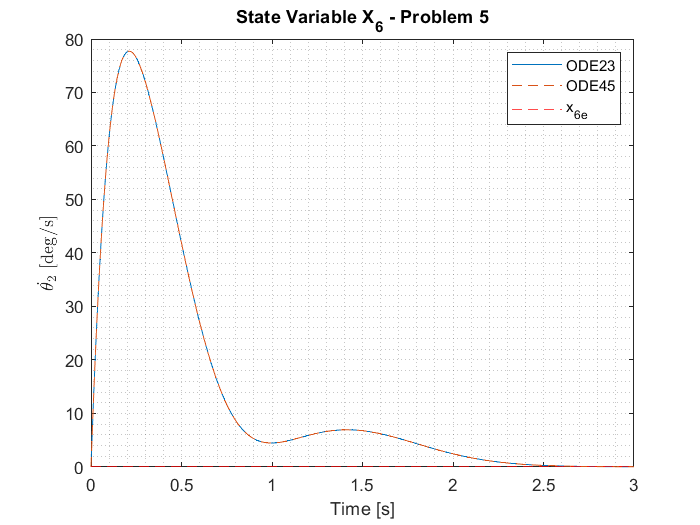

figure
plot(time,X_ode23(:,6)*180/pi,time, X_ode45(:,6)*180/pi,'--')
yline(xe(6)*180/pi,'--r')
title('State Variable X_6 - Problem 5')
ylabel('$\dot{\theta_2}$ [deg/s]','Interpreter','latex')
grid minor
xlabel('Time [s]')
legend('ODE23','ODE45','x_6_e')

## Problem 6 - Output Feedback Controller Design

% Get dimensions of C
[p,~]   = size(C);

cvx_begin sdp quiet

% Variable definition
variable P(n, n) symmetric
variable N(m, p)
variable M(m, m)

% LMIs - output feedback
P*A + A'*P - B*N*C - C'*N'*B' <= -eps*eye(n)
B*M == P*B
P >= eps*eye(n);
cvx_end

disp('The output feedback controller applied to the non-linear model is: u = -K*del_y + u_e')

The output feedback controller applied to the non-linear model is: u = -K*del_y + u_e



$$u = u_e + \delta u = u_e  -K\delta y = u_e - K(y - y_e) = u_e - Ky +K y_e$$


disp('The control gains for the applied control law are:')

The control gains for the applied control law are:


% compute K matrix for output feedback controller
K0 = M\N 

K0 =     1.1673    0.3313    0.4428
   -0.0413    4.1491    0.8682
   -0.0446    0.7837    5.4127


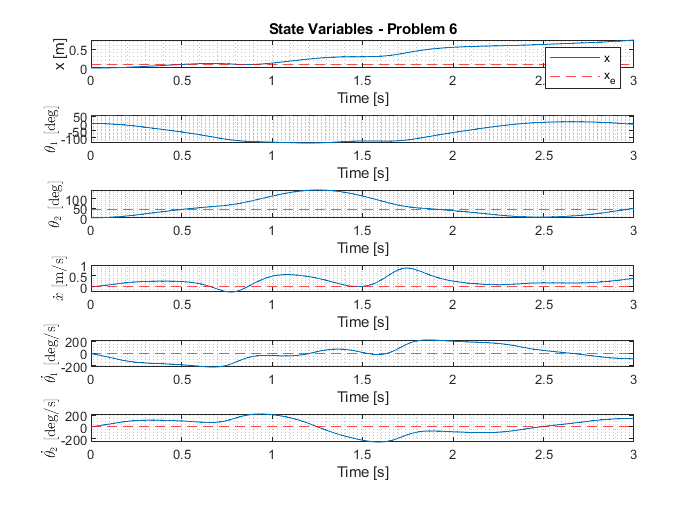

% ODE45 Function call
[~, X_output] = ode45(@(t,x) OutputControlledDIPC_3([], x, ye, ue, K0, m1_num, m2_num, M_num, L1_num, L2_num, g_num), time, x0, options);

figure
subplot(611)
plot(time,X_output(:,1))
yline(xe(1),'--r')
legend('x','x_e')
title('State Variables - Problem 6')
ylabel('x [m]')
grid minor
xlabel('Time [s]')
subplot(612)
plot(time,X_output(:,2)*180/pi)
yline(xe(2)*180/pi,'--r')
ylabel('$\theta_1$ [deg]','Interpreter','latex')
grid minor
xlabel('Time [s]')
subplot(613)
plot(time,X_output(:,3)*180/pi)
yline(xe(3)*180/pi,'--r')
ylabel('$\theta_2$ [deg]','Interpreter','latex')
grid minor
xlabel('Time [s]')
subplot(614)
plot(time,X_output(:,4))
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
yline(xe(4),'--r')
grid minor
xlabel('Time [s]')
subplot(615)
plot(time,X_output(:,5)*180/pi)
yline(xe(5)*180/pi,'--r')
ylabel('$\dot{\theta_1}$ [deg/s]','Interpreter','latex')
xlabel('Time [s]')
grid minor
subplot(616)
plot(time,X_output(:,6)*180/pi)
yline(xe(6)*180/pi,'--r')
ylabel('$\dot{\theta_2}$ [deg/s]','Interpreter','latex')
grid minor
xlabel('Time [s]')

## Problem 7 - Combined Controller- Observer Compensator

% Check system observability
ob     = obsv(A,C);

if rank(ob) == length(A)
    disp('The pair (A,C) is observable')
end

The pair (A,C) is observable


% Observer Robustness Term
alpha_L = 8;

% Use CVX to solve matrix inequality and determine L 
cvx_begin sdp quiet

% Variable definition
variable P(n, n) symmetric
variable Y(n, p)

% LMI with robustness term (all eigenvalues less than -2)
A'*P + P*A - C'*Y' - Y*C + 4*alpha_L*P <= -eps*eye(n);
P >= eps*eye(n) 
cvx_end

disp('The control gains for the Luenberger observer are:')

The control gains for the Luenberger observer are:


% solver for observer gain matrix
L           = P\Y

L = 	1.0e+03 *

    0.0496    0.0001   -0.0002
    0.0032    0.1169   -0.0522
   -0.0014   -0.0504    0.1087
    1.0603    0.0023   -0.0083
    0.0602    2.6755   -1.2292
   -0.0321   -1.1452    2.4280


disp('The Luenberger observer takes the form of:')

The Luenberger observer takes the form of:



$$\delta \dot{\tilde{x}}= \dot{\tilde{x}} =  (A - LC)\delta \tilde{x} + (B - LD) \delta u + L\delta y 
\\
\delta u = -K \delta\tilde{x}
\\
\delta \tilde{x} = \tilde{x} - x_e$$


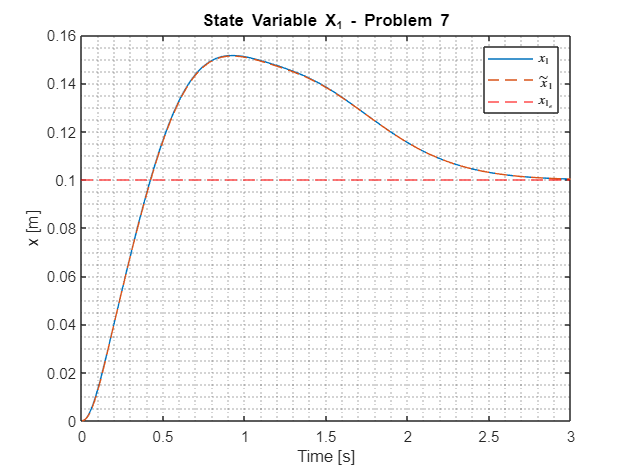

% Observer IC
z0          = zeros(6,1);

% ODE45 Function call
[~, X_comp] = ode45(@(t,x) CombinedCompensatorDIPC([], x, xe, ye, ue, K, L, A, B, C, D, m1_num, m2_num, M_num, L1_num, L2_num, g_num),...
               time, [x0;z0], options);

figure
plot(time,X_comp(:,1),time, X_comp(:,7),'--')
yline(xe(1),'--r')
title('State Variable X_1 - Problem 7')
legend('$x_1$','$\tilde{x}_1$','$x_{1_e}$','Interpreter','latex')
ylabel('x [m]')
grid minor
xlabel('Time [s]')

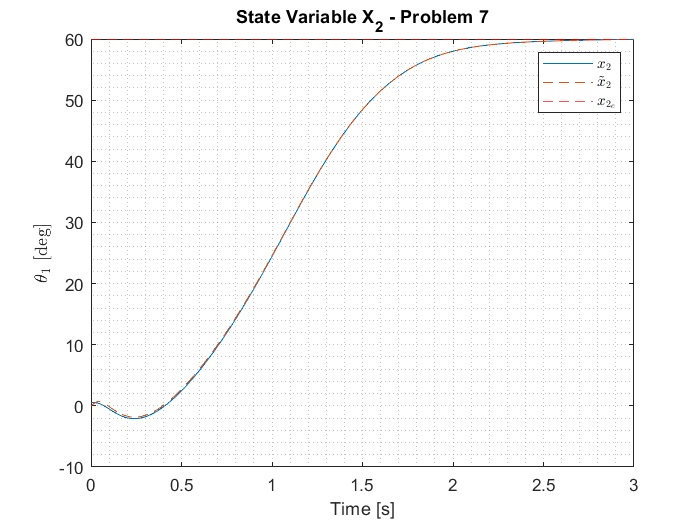

figure
plot(time,X_comp(:,2)*180/pi,time, X_comp(:,8)*180/pi,'--')
yline(xe(2)*180/pi,'--r')
title('State Variable X_2 - Problem 7')
legend('$x_2$','$\tilde{x}_2$','$x_{2_e}$','Interpreter','latex')
ylabel('$\theta_1$ [deg]','Interpreter','latex')
grid minor
xlabel('Time [s]')

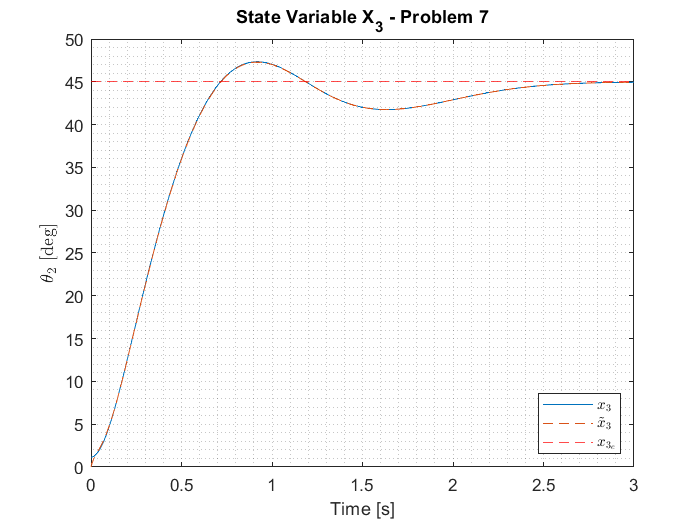

figure
plot(time,X_comp(:,3)*180/pi,time, X_comp(:,9)*180/pi,'--')
yline(xe(3)*180/pi,'--r')
title('State Variable X_3 - Problem 7')
legend('$x_3$','$\tilde{x}_3$','$x_{3_e}$','Interpreter','latex','Location','southeast')
ylabel('$\theta_2$ [deg]','Interpreter','latex')
grid minor
xlabel('Time [s]')

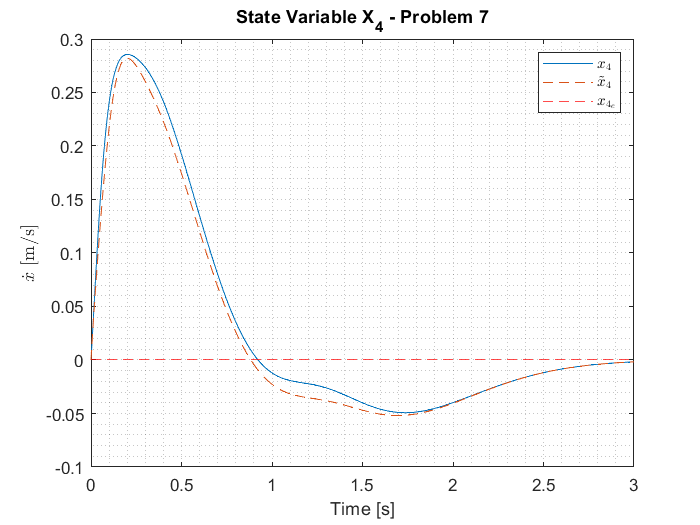

figure
plot(time,X_comp(:,4),time, X_comp(:,10),'--')
yline(xe(4),'--r')
title('State Variable X_4 - Problem 7')
legend('$x_4$','$\tilde{x}_4$','$x_{4_e}$','Interpreter','latex')
ylabel('$\dot{x}$ [m/s]','Interpreter','latex')
grid minor
xlabel('Time [s]')

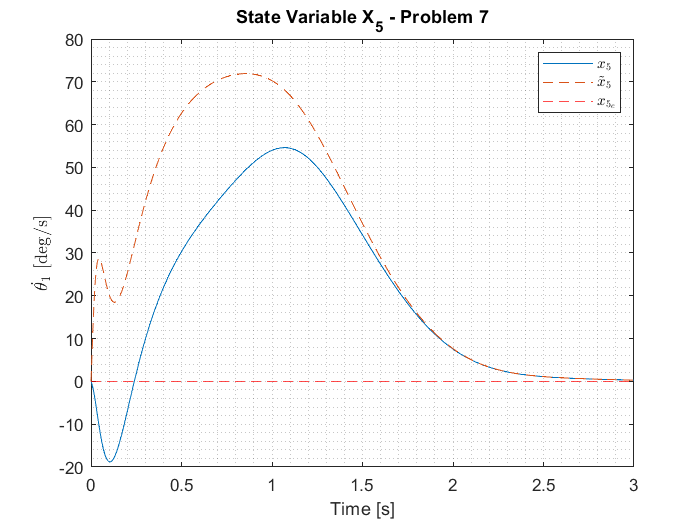

figure
plot(time,X_comp(:,5)*180/pi,time, X_comp(:,11)*180/pi,'--')
yline(xe(5)*180/pi,'--r')
title('State Variable X_5 - Problem 7')
ylabel('$\dot{\theta_1}$ [deg/s]','Interpreter','latex')
xlabel('Time [s]')
grid minor
legend('$x_5$','$\tilde{x}_5$','$x_{5_e}$','Interpreter','latex')

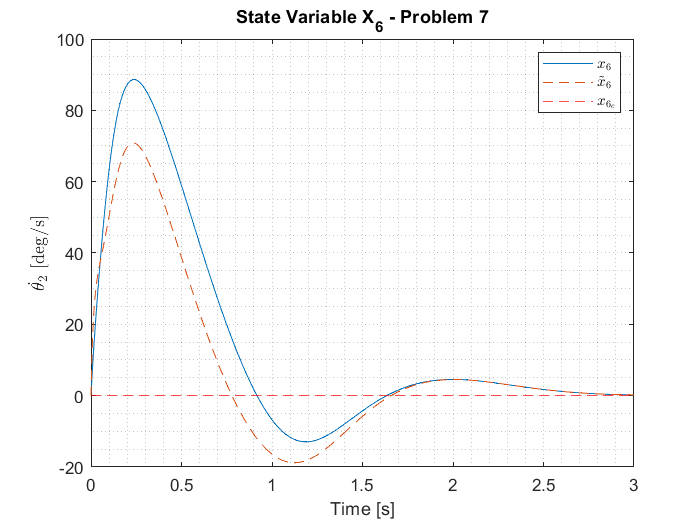

figure
plot(time,X_comp(:,6)*180/pi,time, X_comp(:,12)*180/pi,'--')
yline(xe(6)*180/pi,'--r')
title('State Variable X_6 - Problem 7')
ylabel('$\dot{\theta_2}$ [deg/s]','Interpreter','latex')
grid minor
xlabel('Time [s]')
legend('$x_6$','$\tilde{x}_6$','$x_{6_e}$','Interpreter','latex')

## Functions

% Non-linear DIPC Model with single input

function xdot = DIPC_1(t, x ,u, m1, m2, M, L1, L2, g)

% States and inputs
x1      = x(1,1); % x
x2      = x(2,1); % theta_1
x3      = x(3,1); % theta_2
x4      = x(4,1); % xdot
x5      = x(5,1); % theta_1_dot
x6      = x(6,1); % theta_2_dot


% Equations of Motion
x1dot   = x4;   % xdot
x2dot   = x5;   % theta_1_dot
x3dot   = x6;   % theta_2_dot

% x_ddot
x4dot   = (2*m1*u + m2*u - m2*u*cos(2*x2 - 2*x3) - g*m1^2*sin(2*x2) +...
          2*L1*m1^2*x5^2*sin(x2) - g*m1*m2*sin(2*x2) +...
          2*L1*m1*m2*x5^2*sin(x2) + L2*m1*m2*x6^2*sin(x3) +...
          L2*m1*m2*x6^2*sin(2*x2 - x3))/(2*M*m1 + M*m2 + m1*m2 -...
          m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3));

% theta_1_ddot
x5dot   = -(m1*u*cos(x2) + (m2*u*cos(x2))/2 - (m2*u*cos(x2 - 2*x3))/2 -...
           g*m1^2*sin(x2) - M*g*m1*sin(x2) - (M*g*m2*sin(x2))/2 -...
           g*m1*m2*sin(x2) + (L1*m1^2*x5^2*sin(2*x2))/2 - (M*g*m2*...
           sin(x2 - 2*x3))/2 + (L2*m1*m2*x6^2*sin(x2 + x3))/2 + ...
           L2*M*m2*x6^2*sin(x2 - x3) + (L2*m1*m2*x6^2*sin(x2 - x3))/2 +...
           (L1*m1*m2*x5^2*sin(2*x2))/2 + (L1*M*m2*x5^2*sin(2*x2 - 2*x3))/2)...
           /(L1*(M*m1 + (M*m2)/2 + (m1*m2)/2 - (m1^2*cos(2*x2))/2 + m1^2/2 ...
           - (m1*m2*cos(2*x2))/2 - (M*m2*cos(2*x2 - 2*x3))/2));

% theta_2_ddot
x6dot   = ((m1*u*cos(2*x2 - x3))/2 - (m2*u*cos(x3))/2 - (m1*u*cos(x3))/2 +...
          (m2*u*cos(2*x2 - x3))/2 - (M*g*m1*sin(2*x2 - x3))/2 - ...
          (M*g*m2*sin(2*x2 - x3))/2 + (M*g*m1*sin(x3))/2 + ...
          (M*g*m2*sin(x3))/2 + L1*M*m1*x5^2*sin(x2 - x3) +...
          L1*M*m2*x5^2*sin(x2 - x3) + (L2*M*m2*x6^2*sin(2*x2 - 2*x3))/2)/...
          (L2*(M*m1 + (M*m2)/2 + (m1*m2)/2 - (m1^2*cos(2*x2))/2 + m1^2/2 -...
          (m1*m2*cos(2*x2))/2 - (M*m2*cos(2*x2 - 2*x3))/2));

xdot    = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];
end
 

% Non-linear DIPC Model with two inputs

function xdot = DIPC_2(t, x, u, m1, m2, M, L1, L2, g)

% Define State and Input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot
u1          = u(1,1);
u2          = u(2,1);

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = ((m2*u2*cos(x2 - 2*x3))/2 - (m2*u2*cos(x2))/2 - m1*u2*cos(x2) +...
           L1*m1*u1 + (L1*m2*u1)/2 - (L1*g*m1^2*sin(2*x2))/2 + L1^2*m1^2*x5^2*sin(x2)...
           - (L1*m2*u1*cos(2*x2 - 2*x3))/2 - (L1*g*m1*m2*sin(2*x2))/2 +...
           L1^2*m1*m2*x5^2*sin(x2) + (L1*L2*m1*m2*x6^2*sin(2*x2 - x3))/2 + ...
           (L1*L2*m1*m2*x6^2*sin(x3))/2)/(L1*(M*m1 + (M*m2)/2 + (m1*m2)/2 -...
           (m1^2*cos(2*x2))/2 + m1^2/2 - (m1*m2*cos(2*x2))/2 - (M*m2*cos(2*x2 - 2*x3))/2));

% theta_1_ddot
x5dot       = (M*u2 + m1*u2 + (m2*u2)/2 - (m2*u2*cos(2*x3))/2 - L1*m1*u1*cos(x2) -...
           (L1*m2*u1*cos(x2))/2 + (L1*m2*u1*cos(x2 - 2*x3))/2 + L1*g*m1^2*sin(x2) -...
           (L1^2*m1^2*x5^2*sin(2*x2))/2 - (L1^2*m1*m2*x5^2*sin(2*x2))/2 -...
           (L1^2*M*m2*x5^2*sin(2*x2 - 2*x3))/2 + L1*M*g*m1*sin(x2) +...
           (L1*M*g*m2*sin(x2))/2 + L1*g*m1*m2*sin(x2) +...
           (L1*M*g*m2*sin(x2 - 2*x3))/2 - (L1*L2*m1*m2*x6^2*sin(x2 + x3))/2 -...
           L1*L2*M*m2*x6^2*sin(x2 - x3) - (L1*L2*m1*m2*x6^2*sin(x2 - x3))/2)...
           /(L1^2*(M*m1 + (M*m2)/2 + (m1*m2)/2 - (m1^2*cos(2*x2))/2 + m1^2/2 -...
           (m1*m2*cos(2*x2))/2 - (M*m2*cos(2*x2 - 2*x3))/2));

% theta_2_ddot
x6dot       = (m1*u2*cos(x2 + x3) - m1*u2*cos(x2 - x3) - m2*u2*cos(x2 - x3) -...
           2*M*u2*cos(x2 - x3) + m2*u2*cos(x2 + x3) - L1*m1*u1*cos(x3) - ...
           L1*m2*u1*cos(x3) + L1*m1*u1*cos(2*x2 - x3) + L1*m2*u1*cos(2*x2 - x3) -...
           L1*M*g*m1*sin(2*x2 - x3) - L1*M*g*m2*sin(2*x2 - x3) + L1*M*g*m1*sin(x3) +...
           L1*M*g*m2*sin(x3) + 2*L1^2*M*m1*x5^2*sin(x2 - x3) +...
           2*L1^2*M*m2*x5^2*sin(x2 - x3) + L1*L2*M*m2*x6^2*sin(2*x2 - 2*x3))/...
           (L1*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 ...
           - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));

xdot        = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

end

% Non-linear DIPC model with three inputs
function xdot = DIPC_3(t, x, u, m1, m2, M, L1, L2, g)

% Define State and Input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot
u1          = u(1,1);
u2          = u(2,1);
u3          = u(3,1);

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


xdot        = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

end

% DIPC Lagrangian
function L = DIPC_Lagrangian(t,x, x_dot, theta1, theta_dot_1, theta2, theta_dot_2, M, m1,m2, L1, L2, g)

% Lagrangian for DIPC from HW1
L    = (m2*(x_dot(t) + L1*cos(theta1(t))*theta_dot_1(t) + L2*cos(theta2(t))*...
       theta_dot_2(t))^2)/2 + (m1*(x_dot(t) + L1*cos(theta1(t))*...
       theta_dot_1(t))^2)/2 + (m2*(L1*sin(theta1(t))*theta_dot_1(t) +...
       L2*sin(theta2(t))*theta_dot_2(t))^2)/2 + (M*x_dot(t)^2)/2 + ...
       (L1^2*m1*sin(theta1(t))^2*theta_dot_1(t)^2)/2 - ...
       L1*g*m1*cos(theta1(t)) - L1*g*m2*cos(theta1(t)) - L2*g*m2*cos(theta2(t));

end

% Controlled Non-linear model with 3 inputs
function xdot = ControlledDIPC_3(t, x, xe, ue, K, m1, m2, M, L1, L2, g)

% Define State and Input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot

% Control Law 
u           = -K*x(:,1) + K*xe + ue;
u1          = u(1);
u2          = u(2);
u3          = u(3);

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


xdot        = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

end

% Output Controlled Non-linear model with 3 inputs
function xdot = OutputControlledDIPC_3(t, x, ye, ue, K, m1, m2, M, L1, L2, g)

% Define State and Input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot

% output
y           = [x1;x2;x3];

% Control Law 
u           = -K*y + K*ye + ue;
u1          = u(1);
u2          = u(2);
u3          = u(3);

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


xdot        = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

end

function xdot = CombinedCompensatorDIPC(t, x, xe, ye, ue, K, L, A, B, C, D, m1, m2, M, L1, L2, g)

% Define State, state estimates, and input Vectors
x1          = x(1,1);  % x
x2          = x(2,1);  % theta_1
x3          = x(3,1);  % theta_2
x4          = x(4,1);  % xdot
x5          = x(5,1);  % theta_1_dot
x6          = x(6,1);  % theta_2_dot
x1_tilde    = x(7,1);  % x1_tilde - estimate of x
x2_tilde    = x(8,1);  % x2_tilde - estimate of theta_1
x3_tilde    = x(9,1);  % x3_tilde - estimate of theta_2
x4_tilde    = x(10,1); % x4_tilde - estimate of xdot
x5_tilde    = x(11,1); % x5_tilde - estimate of theta_1_dot
x6_tilde    = x(12,1); % x6_tilde - estimate of theta_2_dot

x_tilde     = [x1_tilde;x2_tilde;x3_tilde;x4_tilde;x5_tilde;x6_tilde];

% Estimated state pertubation: z = delta_xtilde
z           = x_tilde - xe;

% Control Law: u = -K*z + ue
del_u       = -K*z;
u           = del_u + ue;
u1          = u(1);
u2          = u(2);
u3          = u(3);

% State Dynamics
x1dot       = x4;   % xdot
x2dot       = x5;   % theta_1_dot
x3dot       = x6;   % theta_2_dot

% x_ddot
x4dot       = (L2*m2*u2*cos(x2 - 2*x3) - L1*m1*u3*cos(x3) - L2*m2*u2*cos(x2)...
               - L1*m2*u3*cos(x3) - 2*L2*m1*u2*cos(x2) + 2*L1*L2*m1*u1 + L1*L2*m2*u1...
               + L1*m1*u3*cos(2*x2 - x3) + L1*m2*u3*cos(2*x2 - x3) -...
               L1*L2*m2*u1*cos(2*x2 - 2*x3) - L1*L2*g*m1^2*sin(2*x2) +...
               2*L1^2*L2*m1^2*x5^2*sin(x2) - L1*L2*g*m1*m2*sin(2*x2) +...
               L1*L2^2*m1*m2*x6^2*sin(2*x2 - x3) + 2*L1^2*L2*m1*m2*x5^2*sin(x2) +...
               L1*L2^2*m1*m2*x6^2*sin(x3))/(L1*L2*(2*M*m1 + M*m2 + m1*m2 -...
               m1^2*cos(2*x2) + m1^2 - m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));
 
% theta_1_ddot
x5dot       = -(L2*m2*u2*cos(2*x3) - 2*L2*m1*u2 - L2*m2*u2 - 2*L2*M*u2 -...
                2*L1*L2*g*m1^2*sin(x2) + 2*L1*M*u3*cos(x2)*cos(x3) +...
                2*L1*M*u3*sin(x2)*sin(x3) + L1^2*L2*m1^2*x5^2*sin(2*x2) +...
                2*L1*m1*u3*sin(x2)*sin(x3) + 2*L1*m2*u3*sin(x2)*sin(x3) +...
                2*L1*L2*m1*u1*cos(x2) + L1*L2*m2*u1*cos(x2) - 2*L1*L2*M*g*m1*sin(x2)...
                - L1*L2*M*g*m2*sin(x2) - L1*L2*m2*u1*sin(2*x3)*sin(x2) -...
                2*L1*L2*g*m1*m2*sin(x2) + L1^2*L2*m1*m2*x5^2*sin(2*x2) -...
                L1*L2*m2*u1*cos(2*x3)*cos(x2) - L1*L2*M*g*m2*cos(2*x3)*sin(x2) +...
                L1*L2*M*g*m2*sin(2*x3)*cos(x2) - L1^2*L2*M*m2*x5^2*cos(2*x2)*sin(2*x3) +...
                L1^2*L2*M*m2*x5^2*cos(2*x3)*sin(2*x2) - 2*L1*L2^2*M*m2*x6^2*cos(x2)*sin(x3) +...
                2*L1*L2^2*M*m2*x6^2*cos(x3)*sin(x2) + 2*L1*L2^2*m1*m2*x6^2*cos(x3)*sin(x2))/...
                (L1^2*L2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
                m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


% theta_2_ddot
x6dot       = (L1*m1^2*u3 + L1*m2^2*u3 - L1*m1^2*u3*cos(2*x2) - L1*m2^2*u3*cos(2*x2) +...
              L2*m2^2*u2*cos(x2 + x3) + 2*L1*M*m1*u3 + 2*L1*M*m2*u3 + 2*L1*m1*m2*u3 -...
              L2*m2^2*u2*cos(x2 - x3) - L2*m1*m2*u2*cos(x2 - x3) - L1*L2*m2^2*u1*cos(x3) -...
              2*L1*m1*m2*u3*cos(2*x2) + L1*L2*m2^2*u1*cos(2*x2 - x3) +...
              L2*m1*m2*u2*cos(x2 + x3) - 2*L2*M*m2*u2*cos(x2 - x3) - L1*L2*m1*m2*u1*cos(x3) +...
              L1*L2*M*g*m2^2*sin(x3) + 2*L1^2*L2*M*m2^2*x5^2*sin(x2 - x3) +...
              L1*L2*m1*m2*u1*cos(2*x2 - x3) + L1*L2^2*M*m2^2*x6^2*sin(2*x2 - 2*x3) -...
              L1*L2*M*g*m2^2*sin(2*x2 - x3) - L1*L2*M*g*m1*m2*sin(2*x2 - x3) +...
              L1*L2*M*g*m1*m2*sin(x3) + 2*L1^2*L2*M*m1*m2*x5^2*sin(x2 - x3))/...
              (L1*L2^2*m2*(2*M*m1 + M*m2 + m1*m2 - m1^2*cos(2*x2) + m1^2 -...
              m1*m2*cos(2*x2) - M*m2*cos(2*x2 - 2*x3)));


xdot(1:6,1) = [x1dot;x2dot;x3dot;x4dot;x5dot;x6dot];

% Output vector - x, theta_1, theta_2
y           = [x1;x2;x3];

% Output pertubation vector
del_y       = y - ye;

% Observer Dynamics
del_y_tilde = C*z + D*del_u;
zdot        = A*z + B*del_u + L*(del_y - del_y_tilde);

xdot(7:12,1)= zdot;

end